%METODO ALGEBRAICO, JHON PARRA
clear all,clc
%Ingresar funciones de transferencia manualmente para no variar G
%Funcion de transferencia con tiempo muerto , aplicar PADE
s=tf('s');
%G=(1)/((s+2)*(s+1))
%G=(1)/(s*(s+4))
%G=(10)/(s^2-s)
%G=(10)/(s*(s-1)*(s+2))
%G=(2*exp(-0.2*s))/(s*(s+4));G=pade(G)
G=(2)/(s*(s+2))

G =
 
      2
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



[nn,dd] = tfdata(G,'v');
n = length(dd)-1;
m = n-1;
fprintf('Orden minimo controlador: %u \r\n',m) 

Orden minimo controlador: 1 


n = input('Ingrese orden del controlador: ');
fprintf('Número de polos: %u \r\n',m+n+1) 

Número de polos: 3 


polosDeseados = input('Ingrese los polos deseados: Ej [-1 -5 -2+i -2-i]')

polosDeseados =   -8.0000 + 0.0000i  -3.0000 + 1.0000i  -3.0000 - 1.0000i


modelo = poly(polosDeseados)'

modelo =      1
    14
    58
    80


modelo_polinomio = tf(modelo',1)

modelo_polinomio =
 
  s^3 + 14 s^2 + 58 s + 80
 
Continuous-time transfer function.



vPole = [];
vZero = [];
for i=0:1:n
    xn=padarray(dd,[0,i],0,'pre');
    xn=padarray(xn,[0,n-i],0,'pos');
    vPole = [vPole xn'];
    
    xn=padarray(nn,[0,i],0,'pre');
    xn=padarray(xn,[0,n-i],0,'pos');
    vZero = [vZero xn'];
end
A=[vPole vZero] 

A =      1     0     0     0
     2     1     0     0
     0     2     2     0
     0     0     0     2


vecColDel = [];
if n>m 
    fprintf('Como escogio un controlador de orden %u debe eliminar %u columna(s) de la matriz\r\n',n,n-m)
    disp('Nota: Elimine columnas en orden de la menor a la mayor.')
    for i=1:1:n-m
        colDel = input('Ingrese número de columna a eliminar: ej: 3: ');
        vecColDel = [vecColDel,colDel];
        A(:,colDel-i+1) = [];
    end
end
Sol=(A\modelo)';
lenVecColDel = length(vecColDel);
for i=1:1:lenVecColDel
    vecSol1 = Sol(1:vecColDel(i)-1);
    vecSol2 = Sol(vecColDel(i):end);
    Sol = [vecSol1 0 vecSol2];
end
len = length(Sol);
den = Sol(1:len/2);
num = Sol(len/2+1:end);
disp('Controlador: ')

Controlador: 


C = tf(num,den)

C =
 
  17 s + 40
  ---------
   s + 12
 
Continuous-time transfer function.



disp('Modelo: ')

Modelo: 


Tc = feedback(G*C,1)

Tc =
 
         34 s + 80
  ------------------------
  s^3 + 14 s^2 + 58 s + 80
 
Continuous-time transfer function.



disp('Polos modelo: ')

Polos modelo: 


polosModelo = pole(Tc)

polosModelo =   -8.0000 + 0.0000i
  -3.0000 + 1.0000i
  -3.0000 - 1.0000i


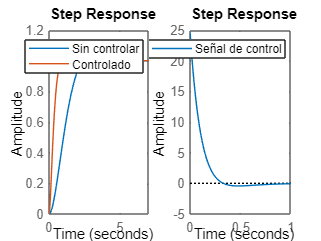

Tk = feedback(G,1);
Suk = feedback(C,G);
subplot(121),step(Tk,Tc), legend('Sin controlar','Controlado')

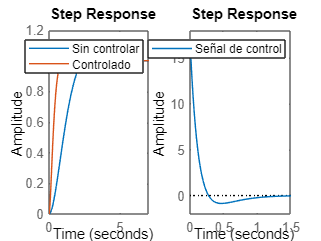

subplot(122),step(Suk), legend('Señal de control')